# Time Synchronous Averaging

- [http://www.phmsociety.org/sites/phmsociety.org/files/phm_submission/2009/phmc_09_5.pdf](http://www.phmsociety.org/sites/phmsociety.org/files/phm_submission/2009/phmc_09_5.pdf)

## Create a signal (use derivative of gaussian)

k = 128; %duration
gauss = exp(-linspace(-2,2,k+1).^2);
gauss_dx = diff(gauss);
gauss_dx = gauss_dx./max(gauss_dx); %normalize

- plot the event of interest

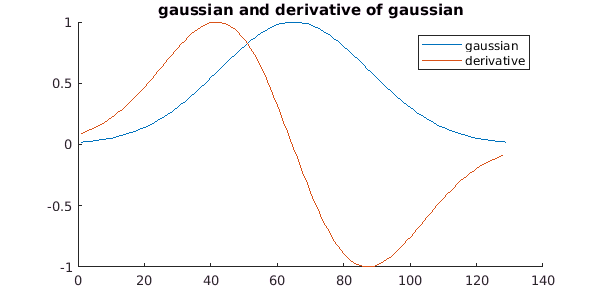

figure('Position', [0,0,600,300]); clf;
hold on;
gauss_plot = plot(gauss);
dx_plot = plot(gauss_dx);
title("gaussian and derivative of gaussian");
legend([gauss_plot, dx_plot], ["gaussian", "derivative"]);
hold off;

## Duplicate the events (gauss_dx)

num_events = 32;
times = randperm(10000-k);
times = times(1:num_events);
data = zeros(1,10000);
for i = 1:num_events
    data(times(i):times(i)+k-1) = gauss_dx;
end
data = data + .5*randn(size(data));

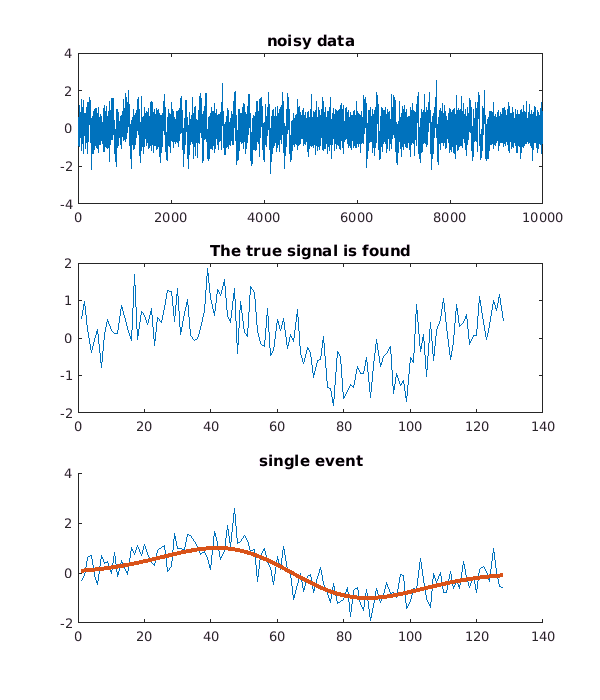

figure('Position', [0,0,600,700]);clf;
subplot(311);
plot(data);
title("noisy data");

subplot(312);
plot(1:k, data(times(3):times(3)+k-1)); %3 chosen at random
title("The true signal is found");

subplot(313);
hold on;
plot(1:k, data(times(10):times(10)+k-1)); %10 chosen at random
plot(1:k, gauss_dx, 'linew',3);
title("single event");
hold off;

## Average the events in the signal

- assumed it is known the time of each event

- for rotating machinery this a function of angular velocity

events = zeros(num_events, k);
for i=1:num_events
    events(i,:) = data(times(i):times(i)+k-1);
end

events_avg = mean(events);

- plot the events

- [https://www.mathworks.com/help/matlab/ref/imagesc.html](https://www.mathworks.com/help/matlab/ref/imagesc.html) 

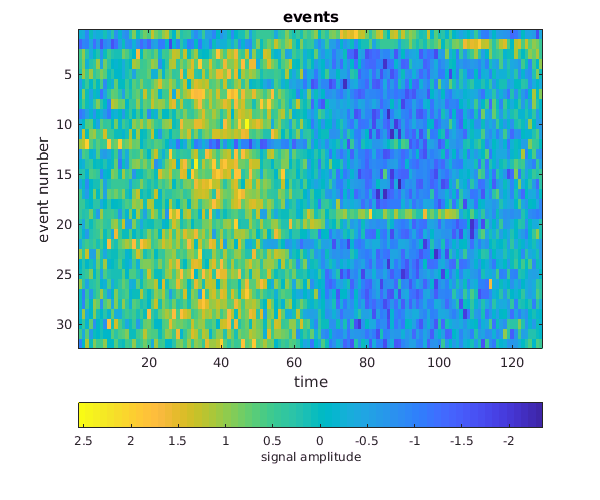

figure('Position', [0,0,600,500]);
imagesc(events);
c = colorbar('southoutside', 'Direction', 'reverse');
c.Label.String = "signal amplitude";
xlabel("time");
ylabel("event number");
title("events");

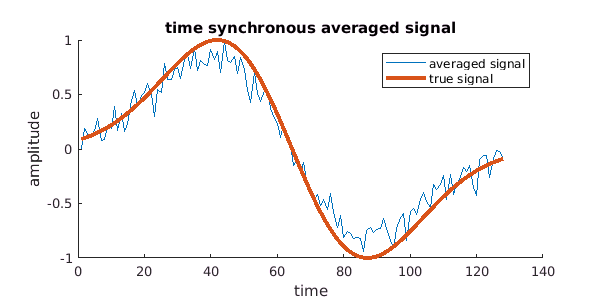


figure('Position', [0,0,600,300]);
hold on;
avg_plot = plot(1:k, events_avg); %the average
true_plot = plot(1:k, gauss_dx, 'linew', 3); %true signal
xlabel("time");
ylabel("amplitude");
legend([avg_plot, true_plot], ["averaged signal", "true signal"]);
title({"";"time synchronous averaged signal"});